**S1. (10 marks) Generate the following random signals in MATLAB. Plot the estimated probability density  function (PDF) and power spectral density (PSD) for each. Comment on how close the estimated PDF and  PSD are to their theoretical values. (see “WGN.mlx” and “WUN.mlx” for guidance). **

**a. White Gaussian Noise, mean = 0, variance = 0.75**

noise_a = randn(1,10000); % Generate one realization of a white Gaussian random process with zero mean and 0.75 variance
noise_a = noise_a - mean(noise_a);
noise_a=noise_a/rms(noise_a)*sqrt(0.75);
m_noise_a = mean(noise_a)

m_noise_a = 1.4921e-17

v_noise_a = var(noise_a)

v_noise_a = 0.7501

Use the "histogram" function to plot the estimated PDFS.

histogram(noise_a,"Normalization","pdf")
axis([-3 3 0 0.5])

Plot the theoretical PDF on top.

xRangeA = linspace(-3,3,1000); %1000 points linearly spaced between -3 to 3.
theoreticalPDF_A = pdf('Normal',xRangeA,0,0.75); % generate theoretical PDF of the white Gaussian random process with zero mean and 0.75 variance between -3 to 3.
hold;

Current plot held


plot(xRangeA,theoreticalPDF_A,'R');
hold;

Current plot released


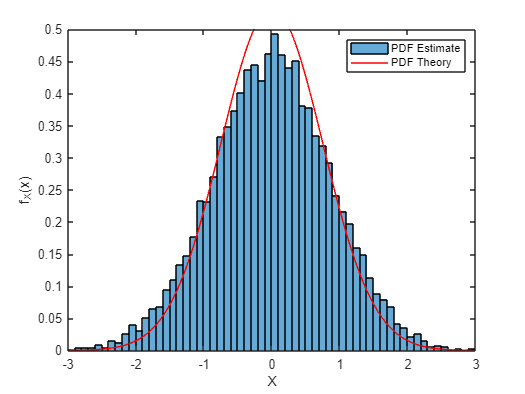

legend('PDF Estimate','PDF Theory')
xlabel('X');ylabel('f_{X}(x)')

Plot the power spectral density using the "pWelch" function.

[noise_a_PSD,w] = pwelch(noise_a,512,256,'centered');%512 sample window, 50% overlap, centered at $\omega$ = 0.
plot(w,2*pi*noise_a_PSD); % 2*pi scaling is needed to properly scale S(w).
xlabel('\omega');ylabel('S_{noise}(\omega)')

Add the theoretical PSD to this graph.

hold;plot(w,0.75*ones(1,length(noise_a_PSD)),'g');hold;

Current plot held
Current plot released


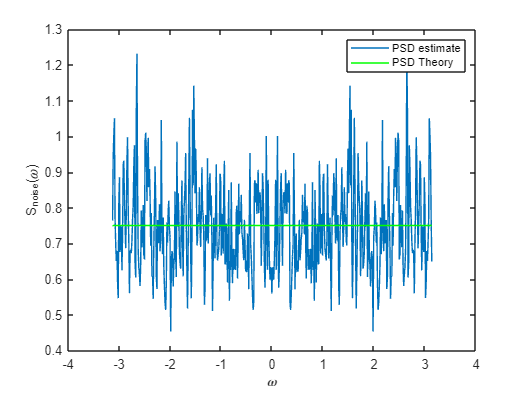

legend('PSD estimate','PSD Theory')

**b. White Uniform Noise, mean = 0, variance = 0.75**

noise_b1 = rand(1, 1000) ; % Generate one realization of a white uniform random process with 0 mean.
noise_b1 = noise_b1 - mean(noise_b1)

noise_b1 =     0.0028   -0.1526   -0.3170    0.1807   -0.2938   -0.2665    0.2163    0.4615   -0.4388    0.3552   -0.2169   -0.1026    0.2927    0.1896   -0.1007   -0.1408    0.2886    0.3891   -0.0146    0.3936   -0.1813    0.4762    0.4149    0.4306   -0.3857   -0.0362    0.1630    0.1238   -0.0820    0.0404    0.4511   -0.3180   -0.0519   -0.0135   -0.3038    0.0971   -0.4553    0.2047    0.0027   -0.3038    0.4333   -0.1875   -0.2402   -0.4339   -0.2343   -0.2868    0.2107    0.2028   -0.4924    0.2842


noise_b1=noise_b1/rms(noise_b1)*sqrt(0.75);
m_noise_b = mean(noise_b1)

m_noise_b = -2.9632e-16

v_noise_b = var(noise_b1)

v_noise_b = 0.7508

Use the "histogram" function to plot the estimated PDF.

histogram(noise_b1,"Normalization","pdf")
axis([-1.5 1.5 0 3])

Plot the theoretical PDF on top.

xRangeB = linspace(-1.5, 1.5, 1000); % 1000 points linearly spaced between -1.5 to 1.5.
theoreticalPDF_B = pdf('Uniform', xRangeB, -1.5, 1.5); % generate theoretical PDF of the uniform distribution between -1.5 to 1.5.
hold;plot(xRangeB,theoreticalPDF_B,'R');hold;

Current plot held
Current plot released


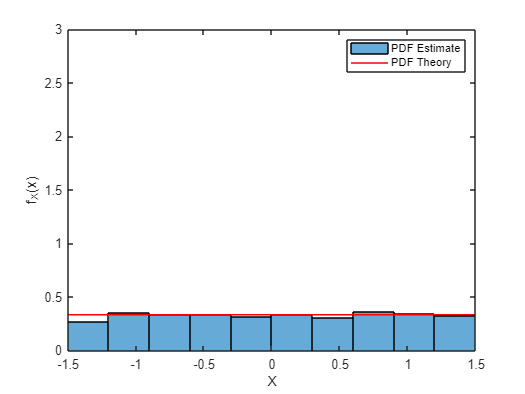

legend('PDF Estimate','PDF Theory')
xlabel('X');ylabel('f_{X}(x)')

Plot the power spectral density using the "pWelch" function, which applies the Welch's periodogram method, to estimate the power spectral density.

[noisePSD_B,w] = pwelch(noise_b1,512,256,'centered');%512 sample window, 50% overlap, centered at $\omega$ = 0.
plot(w,2*pi*noisePSD_B); % 2*pi scaling is needed to properly scale S(w).
xlabel('\omega');ylabel('S_{noise}(\omega)')

Add the theoretical PSD to this graph.  

hold;plot(w,0.75*ones(1,length(noisePSD_B)),'g');hold;

Current plot held
Current plot released


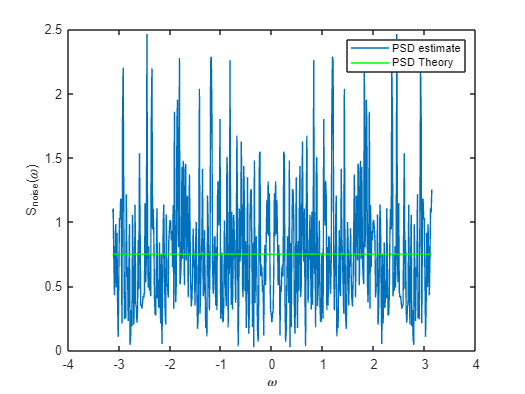

legend('PSD estimate','PSD Theory')

**c. Pink Gaussian Noise, mean = 0, variance = 1**

cn = dsp.ColoredNoise('pink');
noise_c = cn();
noise_c = noise_c - mean(noise_c);
noise_c = noise_c/ std(noise_c);
m_noise_c = mean(noise_c);
v_noise_c = var(noise_c);

Use the "histogram" function to plot the estimated PDF.

histogram(noise_c,"Normalization","pdf")
axis([-3 3 0 0.5])

Plot the theoretical PDF on top.

xRangeC =linspace(-3,3,1000); %1000 points linearly spaced between -3 to 3.
theoreticalPDF_C = pdf('Normal',xRangeC,0,1); % generate theoretical PDF of the white Gaussian random process with zero mean and 1 variance between -3 to 3.
hold;

Current plot held


plot(xRangeC,theoreticalPDF_C,'R');
hold;

Current plot released


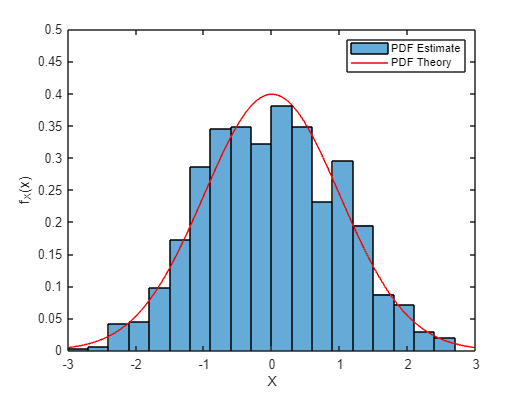

legend('PDF Estimate','PDF Theory')
xlabel('X');ylabel('f_{X}(x)')

Plot the power spectral density using the "pWelch" function.

[noisePSD_C, w] = pwelch(noise_c, 512, 256,'psd');
figure;
plot(w, 10*log10(noisePSD_C), 'b'); % PSD estimate
xlabel('\omega');ylabel('S_{noise}(\omega)')

Add the theoretical PSD to this graph.

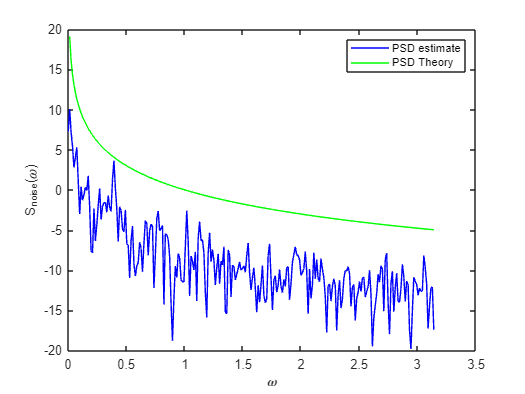

hold on;
PSDPink = 1 ./ w;  %Construct the theoretical PSD of the pink noise process.
plot(w, 10*log10(PSDPink),'g'); 
legend('PSD estimate','PSD Theory')
hold off;